**EE 699 Next Generation Wireless Networks**

**Rishabh Pomaje - 210020036**

**Assignment 01**

My Comments :

- Unable to get the frequency offset working in tandem with the time offset.

- In the interest of time, the multiple receive antenna structure is not implemented. Thus, the current system is 1 x 1.

- While I have implemented my own modulator and demodulator functions, I am unsure of their functional correctness and hence, I am using the lteOFDMModulator and lteOFDMDemodulator for the time being.

- I am using only one subframe that is offset in the time domain by a few samples as the objective is to detect the PSS/ SSS and synchronize. 

clear ;

% Simulation constants
n_runs = 1 ;

% Parameter Constants
N_fft = 128 ;          % Size of the FFT
del_F = 15 * 10 ^ 3 ;  % Sub-carrier spacing
Fs = N_fft * del_F ;   % Sampling Frequency/ Rate
t_sample = 1 / Fs ;    % Sampling Period

% Forced number of Subframes :
num_sf = 1 ;

% Time axes calculations :
slot_duration = 0.5 * 10 ^ -3 ;
subf_duration = 2 * slot_duration ;
rf_duration = 10 * subf_duration ;
total_duration = num_sf * subf_duration ;

t_axes = 0: 1/Fs: total_duration - (1/Fs) ;

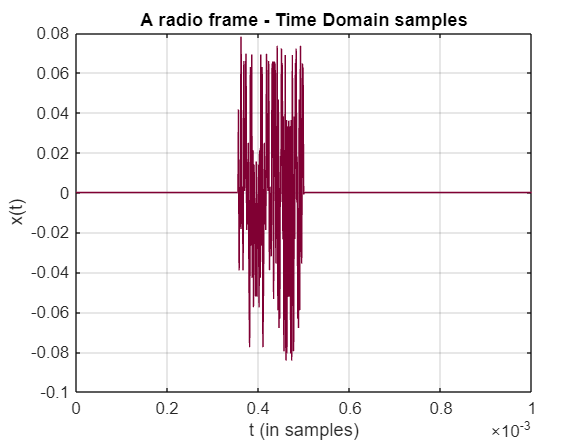

% Demo of the correlation of generated signals in time domain
[x_t, ~, truePSS, trueSSS] = LTEsignalGen(num_sf) ;
plot(t_axes, real(x_t), Color=[0.5, 0, 0.2]) ;
xlabel('t (in samples)') ;
ylabel('x(t)') ;
grid("on") ;
title('A radio frame - Time Domain samples') ;

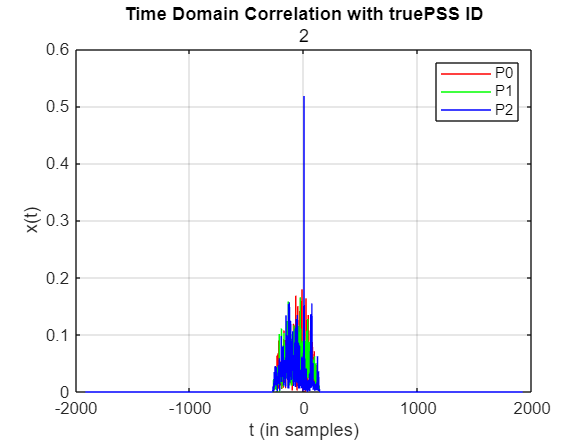

% Creation of reference signals in frequency domain :
[time_refPSS, time_refSSS] = LTErefSignalGen("time") ;
[freq_refPSS, freq_refSSS] = LTErefSignalGen("frequency") ;

cla ;
hold on ;
[c, lags] = xcorr(x_t, time_refPSS(:, 1)) ;
plot(lags, abs(c), Color=[1, 0, 0]) ;
[c, lags] = xcorr(x_t, time_refPSS(:, 2)) ;
plot(lags, abs(c), Color=[0, 1, 0]) ;
[c, lags] = xcorr(x_t, time_refPSS(:, 3)) ;
plot(lags, abs(c), color=[0, 0, 1]) ;
legend('P0', 'P1', 'P2') ;
grid("on") ;
title('Time Domain Correlation with truePSS ID', num2str(truePSS)) ;
hold off;

- PSS and SSS Detection - For AWGN channel 

mse_T0_awgn = [] ;
mse_F0_awgn = [] ;
Pe_PSS_id_awgn = [] ;
Pe_SSS_id_awgn = [] ;

% Simulation routine
% SNR_dB = -2:15 ;
% for SNR = SNR_dB
%     SNR_linear = 10 ^ (SNR / 10) ;
    mu = 0 ;
    % sig = sqrt(1 / (2 * SNR_linear)) ;
    sig = 0 ;
% 
%     t0_error = 0 ;
%     f0_error = 0 ;
%     p_pss_error = 0 ;
%     p_sss_error = 0 ;
    for run_number=1:n_runs
        % Generate a signal
        [x_t, ~, truPSSid, truSSSid] = LTEsignalGen(1) ;

        % Add a frequency offset :: Skipping for now
        f_off_ideal = randi([-500, 500]) ;
        for n=1:length(x_t)
            x_t(n) = exp(1j * 2 * pi * f_off_ideal * n * t_sample) * x_t(n) ;
        end

        % Add a time offset :: In number of samples
        t_off_ideal = randi(9) ;
        x_t = [zeros(t_off_ideal, 1); x_t] ;

        % Channel Reponse : AWGN Channel
        noise_samples = normrnd(mu, sig, size(x_t)) + 1j * normrnd(mu, sig, size(x_t)) ;
        y_t = x_t + noise_samples;

        % Detection of PSS, SSS and estimate of the timing offset :
        [t_off_est, estPSSid, estSSSid] = myLTEreceiver("time", y_t, time_refPSS, time_refSSS, 0, 0) ;

        % Removing the time offset 
        y_t_corrected = y_t(t_off_est+1:end, 1) ;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Function Under Test %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Detection of frequency offset
        % Conversion to frequency domain :
        enb.NDLRB = 6 ;                      % Number of resource blocks
        enb.CellRefP = 1 ;                   % One transmit antenna port
        enb.CyclicPrefix = 'Normal' ;        % Normal cyclic prefix
        enb.DuplexMode = 'FDD' ;             % FDD
        Y_f = lteOFDMDemodulate(enb, y_t) ; 
        Y_f = Y_f(:, 7) ;
        
        % Frequency Domain Correlation method to detect the frequency offset :
        % Initialization
        currPeak = -inf ;
        offset = 0 ;
        pssID = 0 ;
        % Loop through PSS 0, 1, and 2
        for idx = 1:3
            Z = Y_f .* conj([zeros(5, 1); freq_refPSS(:, idx); zeros(5, 1)]) ;
            z = ifft(Z) ;
            [Peak, ~] = max(abs(z));
            if Peak > currPeak
                pssID = idx - 1;   % Zero-based PSS ID (PSS 0, PSS 1, PSS 2)
                currPeak = Peak;
                offset = mean(angle(Z)) ;
            end
        end
        offset * 1920000 / (2 * pi * 62)
        f_off_ideal 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Analysis of the results
    %     t0_error = t0_error + ((t_off_est - t_off_ideal) ^ 2) ;
    %     if (truPSSid ~= estPSSid)
    %         p_pss_error = p_pss_error + 1 ;
    %     end
    %     if (truSSSid ~= estSSSid)
    %         p_sss_error = p_sss_error + 1 ;
    %     end
    end

ans = -1.2653e+03

f_off_ideal = 424

    % mse_T0_awgn = [mse_T0_awgn, (t0_error / n_runs)] ;
    % mse_F0_awgn = [] ;
    % Pe_PSS_id_awgn = [Pe_PSS_id_awgn, (p_pss_error / n_runs)] ;
    % Pe_SSS_id_awgn = [Pe_SSS_id_awgn, (p_sss_error / n_runs)] ;
% end

**Plots for the AWGN channel :**

% ID detection plots
semilogy(SNR_dB, Pe_PSS_id_awgn) ;

Unrecognized function or variable 'SNR_dB'.

hold on ;
semilogy(SNR_dB, Pe_SSS_id_awgn) ;
xlabel('SNR (in dB)') ;
ylabel('P_{error}') ;
legend('P_e(PSS)', 'P_e(SSS)') ;
title('Detection Error Probability of Synchronization Sequence IDs')
grid on ;
hold off ;
plot(SNR_dB, mse_T0_awgn) ;
xlabel('SNR (in dB)') ;
ylabel('MSE(\Delta T_{ideal}, \Delta T_{estimated})') ;
title('Mean Squared Error in Timing Offset Detection') ;
grid on ;

PSS and SSS detection - For Rayleigh Fading + AWGN channel

Additions compared to the previous part : Channel Estimation 

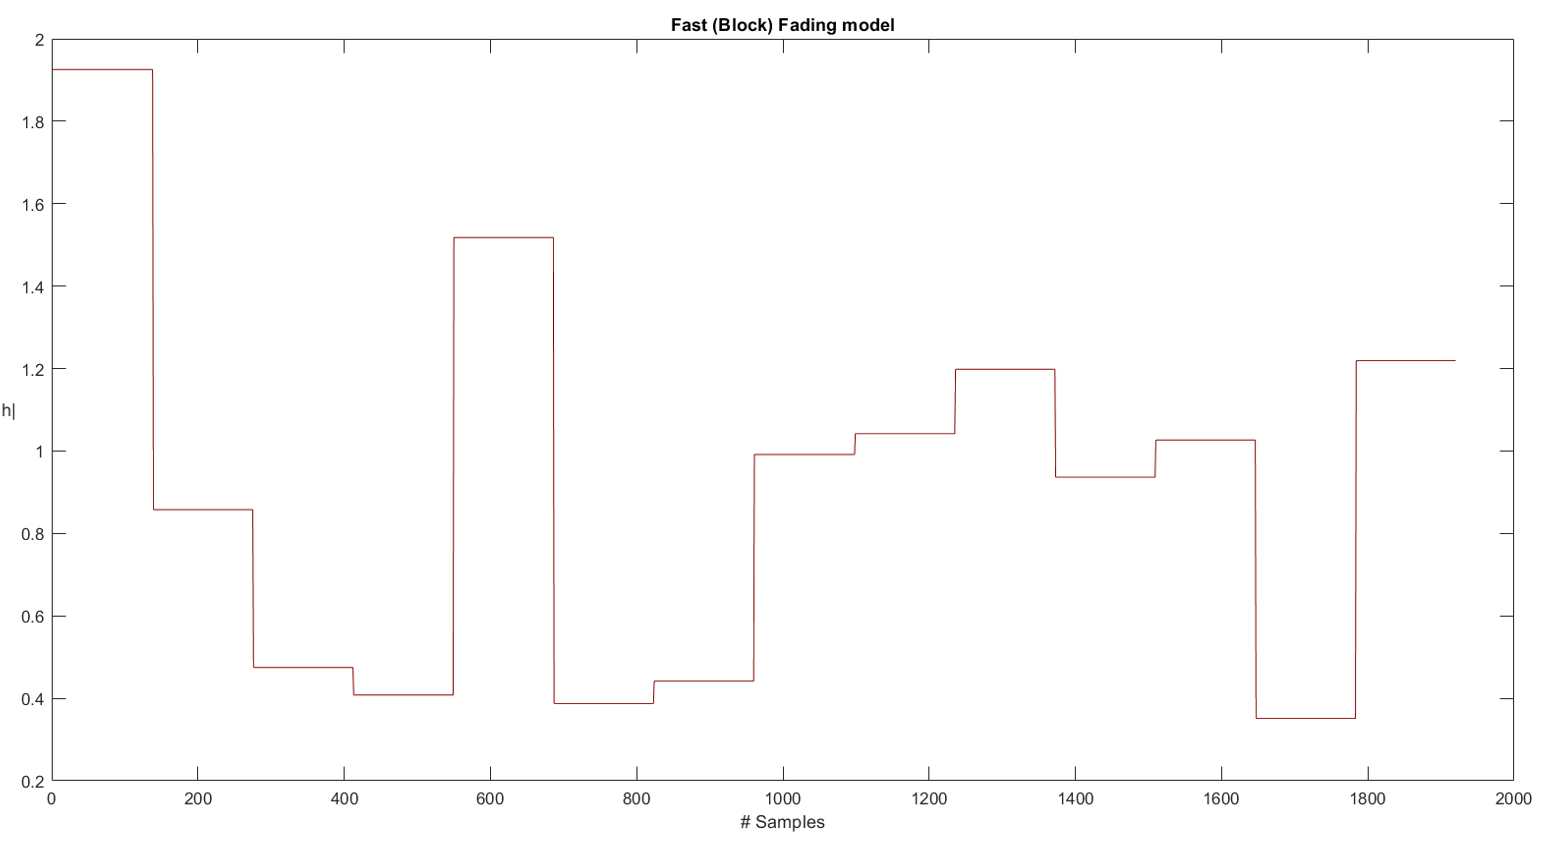

**Plotting the results for Rayleigh Fading Channel **

**Function Definitions:**

function [x_t, X_f, PSS_id, SSS_id] = LTEsignalGen(num_sf)
% Function that generates time domain samples of LTE signal consisting
% of PSS and SSS synchronization signals.
x_t = [] ;
PSS_id = randi([0, 2]) ;
SSS_id = randi([0, 15]) ;
% Cell Settings :
enb.NDLRB = 6;                      % Number of resource blocks
enb.CellRefP = 1;                   % One transmit antenna port
enb.NCellID = 3*SSS_id + PSS_id;    % Cell ID
enb.CyclicPrefix = 'Normal';        % Normal cyclic prefix
enb.DuplexMode = 'FDD';             % FDD
% Generation in frequency domain :
txGrid = [] ;
for i=0:num_sf - 1
    enb.NSubframe = mod(i, 10); % Subframe Index
    subframe = lteDLResourceGrid(enb);

    % Generate synchronizing signals
    pss_symbols = ltePSS(enb) ;
    sss_symbols = lteSSS(enb) ;
    antenna = 0 ;
    pssIndices = ltePSSIndices(enb, antenna) ;
    sssIndinces = lteSSSIndices(enb, antenna) ;

    % Map synchronizing signals to the grid
    subframe(pssIndices) = pss_symbols ;
    subframe(sssIndinces) = sss_symbols ;

    % Collect all the subframes
    txGrid = [txGrid subframe] ;
end
% Frequency Domain signal
X_f = txGrid ;
% Modulation : Conversion to time domain
[x_t,~] = lteOFDMModulate(enb,txGrid) ;
end

function [refPSS, refSSS] = LTErefSignalGen(domain)
% Function to generate the reference time domain or frequency domain
% using lteOFDMModulate
% Cell settings
enb.NDLRB = 6 ;                % Number of resource blocks
enb.CellRefP = 1 ;             % One transmit antenna port
enb.CyclicPrefix = 'Normal';   % Normal cyclic prefix
enb.DuplexMode = 'FDD';        % FDD
enb.NSubframe = 0; % Subframe Index

% Signals of the PSS and SSS for LTE.
refPSS = [] ;
refSSS = [] ;
if (domain == "time")
    % Return the time domain samples
    % PSS sequences : 0 ~ 2
    for PSS_id=0:2
        enb.NCellID = PSS_id ;
        % Generate synchronizing signals
        pss_symbols = ltePSS(enb) ;
        pssIndices = ltePSSIndices(enb) ;

        PSSsubframe = lteDLResourceGrid(enb);
        PSSsubframe(pssIndices) = pss_symbols;

        % Modulation : Conversion to time domain
        [t_pss,~] = lteOFDMModulate(enb,PSSsubframe) ;
        refPSS = [refPSS t_pss] ;
    end
    % SSS sequences : 0 ~ 15
    for SSS_id=0:15
        enb.NCellID = 3*SSS_id;
        % Generate synchronizing signals
        sss_symbols = lteSSS(enb);
        sssIndices = lteSSSIndices(enb);

        SSSsubframe = lteDLResourceGrid(enb);
        SSSsubframe(sssIndices) = sss_symbols;

        % Modulation : Conversion to time domain
        [t_sss,~] = lteOFDMModulate(enb,SSSsubframe) ;
        refSSS = [refSSS t_sss] ;
    end
    % Return the frequency domain samples :
else
    % PSS sequences : 0 ~ 2
    for PSS_id=0:2
        enb.NCellID = PSS_id;  % Cell ID
        % Generate synchronizing signals
        pss_symbols = ltePSS(enb);
        refPSS = [refPSS pss_symbols] ;
    end
    % SSS sequences : 0 ~ 15
    for SSS_id=0:15
        enb.NCellID = 3*SSS_id;  % Cell ID
        % Generate synchronizing signals
        sss_symbols = lteSSS(enb);
        refSSS = [refSSS sss_symbols] ;
    end
end
end

% My implementation of the OFDM Modulator
function [x_t, PSS_id, SSS_id] = myOFDMModulator(num_sf)
x_t = [] ;
PSS_id = randi([0, 2]) ;
SSS_id = randi([0, 15]) ;
% Cell Settings :
enb.NDLRB = 6;                      % Number of resource blocks
enb.CellRefP = 1;                   % One transmit antenna port
enb.NCellID = 3*SSS_id + PSS_id;    % Cell ID
enb.CyclicPrefix = 'Normal';        % Normal cyclic prefix
enb.DuplexMode = 'FDD';             % FDD
% Generation in frequency domain :
for i=0:num_sf - 1
    sf_grid = [] ;
    enb.NSubframe = mod(i, 10); % Subframe Index

    % Generate synchronizing signals
    pss_symbols = ltePSS(enb) ;
    sss_symbols = lteSSS(enb) ;

    % Zero Padding for 128 pt FFT
    pss_symbols = [zeros(33, 1); pss_symbols; zeros(33, 1)] ;
    sss_symbols = [zeros(33, 1); sss_symbols; zeros(33, 1)] ;

    % Taking the FFT
    pss_samples = fftshift(ifft(pss_symbols)) ;
    sss_samples = fftshift(ifft(sss_symbols)) ;

    % Adding the CP
    pss_samples = [pss_samples(120:128, 1); pss_samples] ;
    sss_samples = [sss_samples(120:128, 1); sss_samples] ;

    % Forming the subframe in time domain
    sf_grid = [zeros(686, 1); sss_samples; pss_samples; zeros(960, 1)] ;
    x_t = [x_t sf_grid] ;
end
end

% My implementation of the reference signal generators (only modulation part is mine.)
function [refPSS, refSSS] = myrefSignalGen(domain)
% Function to generate the reference time domain or frequency domain
% Cell settings
enb.NDLRB = 6;                 % Number of resource blocks
enb.CellRefP = 1;              % One transmit antenna port
enb.CyclicPrefix = 'Normal';   % Normal cyclic prefix
enb.DuplexMode = 'FDD';        % FDD
enb.NSubframe = 0; % Subframe Index

% signals of the PSS and SSS for LTE.
refPSS = [] ;
refSSS = [] ;
if (domain == "time")
    % Return the time domain samples
    % PSS sequences : 0 ~ 2
    for PSS_id=0:2
        enb.NCellID = PSS_id;
        % Generate synchronizing signals
        pss_symbols = ltePSS(enb);
        pss_symbols = [zeros(33, 1); pss_symbols; zeros(33, 1)] ;
        t_pss = ifft(fftshift(pss_symbols)) ;

        % Modulation : Conversion to time domain
        refPSS = [refPSS t_pss] ;
    end
    % SSS sequences : 0 ~ 15
    for SSS_id=0:15
        enb.NCellID = 3 * SSS_id;
        % Generate synchronizing signals
        sss_symbols = lteSSS(enb);
        sss_symbols = [zeros(33, 1); pss_symbols; zeros(33, 1)] ;

        % Modulation : Conversion to time domain
        t_sss = ifft(fftshift(sss_symbols)) ;
        refSSS = [refSSS t_sss] ;
    end
else
    % Return the frequency domain samples :
    % PSS sequences : 0 ~ 2
    for PSS_id=0:2
        enb.NCellID = PSS_id;
        % Generate synchronizing signals
        pss_symbols = ltePSS(enb);
        refPSS = [refPSS fftshift(pss_symbols)] ;
    end
    % SSS sequences : 0 ~ 15
    for SSS_id=0:15
        enb.NCellID = 3*SSS_id;
        % Generate synchronizing signals
        sss_symbols = lteSSS(enb);
        refSSS = [refSSS fftshift(sss_symbols)] ;
    end
end
end

function [offset, pssID, sssID] = myLTEreceiver(domain, rxSignal, PSSrefSignal, SSSrefSignal, csi, isCoherentDet)
    % Function that detects and estimates the time and frequency offsets of
    % the impaired LTE signal.
    % First detect the PSS and timing offset :
    % in time domain :
    if domain == "time"
        % Initialization
        currPeak = -inf;   % Initialize to a very low value
        currTimeoff = 0;
        estPSSid = 0;
        % Loop through PSS 0, 1, and 2
        for idx = 1:3
            [c, lags] = xcorr(rxSignal, PSSrefSignal(:, idx));
            [Peak, maxInd] = max(abs(c));
            Timeoff = lags(maxInd);
    
            if Peak > currPeak
                estPSSid = idx - 1;   % Zero-based PSS ID (PSS 0, PSS 1, PSS 2)
                currPeak = Peak;
                currTimeoff = Timeoff;
            end
        end
        offset = currTimeoff ;
        pssID = estPSSid ;
    else
        % Conversion to frequency domain :
        enb.NDLRB = 6 ;                      % Number of resource blocks
        enb.CellRefP = 1 ;                   % One transmit antenna port
        enb.CyclicPrefix = 'Normal' ;        % Normal cyclic prefix
        enb.DuplexMode = 'FDD' ;             % FDD
        Y_f = lteOFDMDemodulate(enb, rxSignal) ;
    
        % Frequency Domain Correlation method to detect the frequency offset :
        % Initialization
        currPeak = -inf ;
        offset = 0 ;
        pssID = 0 ;
        % Loop through PSS 0, 1, and 2
        for idx = 1:3
            Z = Y_f .* conj([zeros(5, 1); PSSrefSignal(:, idx); zeros(5, 1)]) ;
            z = ifft(Z) ;
            [Peak, ~] = max(abs(z));
            if Peak > currPeak
                pssID = idx - 1;   % Zero-based PSS ID (PSS 0, PSS 1, PSS 2)
                currPeak = Peak;
                offset = mean(angle(Z)) ;
            end
        end
    end
    % Always do time domain correlation and detection off the SSS
    % Time domain correlation to detect SSS sequence ID:
    % Initialization
    currPeak = -inf;   % Initialize to a very low value
    sssID = 0;
    % Loop through SSS 0 ~ 15
    for idx = 1:16
        [c, ~] = xcorr(rxSignal, SSSrefSignal(:, idx));
        [Peak, ~] = max(abs(c));
        if Peak > currPeak
            sssID = idx - 1;
            currPeak = Peak;
        end
    end
end